# 6R Puma-Style Manipulator PSDM Example

This example shows how PSDM can be used to derive the regressor for of the dynamics of motion of a PUMA manipulator.

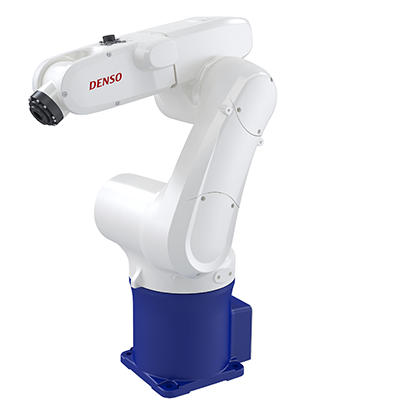

## Derivation

First, we define the DH table of the maniuplator. For the input to this toolbox, DH table must be defined as a $n\times 6%$ double matrix:


$$\text{DH} = \left[\matrix{
a_1 & \alpha_1 & d_1 & \theta_1 & t_1 & s_1 \cr
\vdots &\vdots &\vdots &\vdots &\vdots &\vdots \cr
a_n & \alpha_n & d_n & \theta_n & t_n & s_n \cr
 }\right]$$


where $a_i, \alpha_i, d_i$ and $\theta_i$ are the normal DH parameters, $t_i$ indicates the joint type (0 for revolute, 1 for prismatic) and $s_i$ is either a 1 or a -1, and indicates the direction of the joint. Internally, they are combined to make the DH table:


$$\left|
\matrix{
\text{Link Length } a_i & \text{Link twist } \alpha_i & \text{Link offset} d_i & \text{Joint angle } \theta_i \cr
a_i & \alpha_i & d_i + t_i s_i q_i & \theta_i + (1-t_i)s_i q_i
}
\right|$$


d1 = 132e-3;
d4 = 295e-3;
d6 = 80e-3;
a1 = 75e-3;
a2 = -270e-3;
a3 = -90e-3;
DH =   [a1,       -pi/2,  0,      d1,     0,      1;
        a2,       0,      0,      0,      0,      1;
        a3,       pi/2,   0,      0,      0,      1;
        0,        -pi/2,  0,      d4,     0,      1;
        0,        pi/2,   0,      0,      0,      1;
        0,        0,      0,      d6,     0,      1];

We also need a gravity vector. This is a unit vector and is scaled by the gravitational constant internally. Here, gravity is pointing in the negative y direction.

g = [0; 0; 1];

Finally, we (optionally) need to define a vector of inertial parameters of the robot, $X$. This is **not** needed to run the derivation. But, it can be used to specify certain parameters as being zero. Internally, any parameter which is identically zero in the given $X$ matrix is assumed negligible and is not included in the derivation, leading to simpler results.

$X$ is defined as the concatenation of all the inertial parameters:


$$X = \left[
\matrix{
m_1 & r_{x,1} & r_{y,1} & r_{z,1} & I_{xx,1}& I_{yy,1}& I_{zz,1}& I_{xy,1}& I_{xz,1}& I_{yz,1} \cr
\vdots & \vdots & \vdots & \vdots & \vdots & \vdots & \vdots & \vdots & \vdots & \vdots \cr
m_n & r_{x,n} & r_{y,n} & r_{z,n} & I_{xx,n}& I_{yy,n}& I_{zz,n}& I_{xy,n}& I_{xz,n}& I_{yz,n}
}
\right]$$


Here, we we make no assumptions about any of the parameters, so we can either set X to be a $n\times 10$ matrix of ones, or just give leave it empty.

X = [];

We can also specify the tolerance (default is 1e-11) and verbosity (default is true).

tolerance = 1e-10;
verbosity = true;

Now, we can run the derivation. Because this is a more complex robot, this should take 5-10 minutes to run, depending on the speed of your computer.

[E, P] = PSDM.deriveModel(DH, g, X, tolerance, verbosity);


Running gravity derivation (729 search terms).
		729 terms reduced to 90, Took 0.40 seconds.
		Max Reprojection Error: 4.97e-14.
		Reduced from (90 / 90) to 10 parameters (took 0.992 seconds).
		Reprojection error is 1.39e-13
	Gravity matching done. 10 terms remaining (took 1.46 sec total).


Running accel derivation (93750 search terms).

	Searching in joint 1 (15625 terms)...
		15625 terms reduced to 753, Took 53.31 seconds.
		Max Reprojection Error: 2.66e-14.
		Reduced from (753 / 753) to 34 parameters (took 7.51 seconds).
		Reprojection error is 2.06e-13
	Searching in joint 2 (15625 terms)...
		15625 terms reduced to 329, Took 40.64 seconds.
		Max Reprojection Error: 1.07e-14.
		Reduced from (329 / 329) to 28 parameters (took 1.57 seconds).
		Reprojection error is 4.15e-14
	Searching in joint 3 (15625 terms)...
		15625 terms reduced to 289, Took 42.96 seconds.
		Max Reprojection Error: 7.99e-15.
		Reduced from (289 / 289) to 25 parameters (took 1.36 seconds).
		Reprojection error 

E is the exponent matrix which represents the terms of the final result. These matrices can be inspected in matlab, however they are a bit large to intuite visually.

## Testing

The PSDM model, defined by E and P, can be used either through full knowledge of $X$, the inertial parameters, or through experimental determination of the $\Theta$ regression parameters.

Here, since we do not have experimental data, we can just use the $X$ parameters above to validate the result. Note, this validation has actually already been performed in the derivation above – this is just to illustrate.

First, use the X2Theta function to convert the X matrix into the appropriate regression vector. We assume some arbitrary list of inertial parameters, simulated by a rand function.

DOF = size(DH, 1);
X = rand(DOF, 10)*2;
Theta = PSDM.X2Theta(DH, X, g, E, P, 5000);

Now, define some random poses.

N = 5;

Q = (rand(DOF, N)-0.5) * (2*pi);
Qd = (rand(DOF, N)-0.5);
Qdd = (rand(DOF, N)-0.5);

We can use the newton-euler algorithm to get the inverse dynamics.

tau_rne = PSDM.inverseDynamicsNewton(DH, X, Q, Qd, Qdd, 2, g)

tau_rne =      -0.45173       7.6464       9.7556       4.0661      -0.3286
      -1.1552       25.143      -37.455       37.113       12.875
      -6.1523       20.822      -31.893       41.543       6.5399
       6.1592       -22.75        1.118      -21.176       4.3173
      -9.3784       4.6895       7.3747        37.18        4.551
       4.5326        5.927       10.777        1.335       1.4655


Then use the PSDM model, and check the error:

tau_psdm = PSDM.inverseDynamics(E, P, Theta, Q, Qd, Qdd)

tau_psdm =      -0.45173       7.6464       9.7556       4.0661      -0.3286
      -1.1552       25.143      -37.455       37.113       12.875
      -6.1523       20.822      -31.893       41.543       6.5399
       6.1592       -22.75        1.118      -21.176       4.3173
      -9.3784       4.6895       7.3747        37.18        4.551
       4.5326        5.927       10.777        1.335       1.4655


fprintf('Max inverse dynamics error: %.5g\n', max(abs(tau_rne - tau_psdm), [], 'all'));

Max inverse dynamics error: 1.6634e-10


We can also validate the forward dynamic model by ensuring that we get the same joint accelerations we started with.

Qdd_psdm = PSDM.forwardDynamics(E, P, Theta, Q, Qd, tau_psdm)

Qdd_psdm =       -0.3225      0.35661      0.48834      0.27846     -0.22899
      0.41458    -0.078981    -0.011862   -0.0099452     -0.49084
     -0.12135     -0.08936      0.39126      -0.3789      -0.0818
      -0.2377      0.29427    0.0091547     -0.46061      0.16243
      0.45805      0.35713      0.39781      0.39206       0.4118
      0.30233     0.092792       0.4706      0.11821       0.3072


fprintf('Max forward dynamics error: %.5g\n', max(abs(Qdd_psdm - Qdd), [], 'all'));

Max forward dynamics error: 4.4353e-14


The errors should be negligible (machine precision levels).

## Faster real time code

The default PSDM functions for inverse and forward dynamics are a bit slow since there is some pre-processing to be done at each step, and complex indexing which is slow for matlab.

However, because the model is quite nicely organized in E and P, we can procedurally create matlab functions which are much faster than the default functions, specifically for a given $\{E, P, \Theta\}$ tuple.

Add the temp directory and define some filenames for the functions:

addpath(fullfile(utilities.PSDMDir, 'temp'));
filename_inverse = fullfile( utilities.PSDMDir, 'temp', 'PSDM_inverseDynamics_denso6R.m');
filename_forward = fullfile( utilities.PSDMDir, 'temp', 'PSDM_forwardDynamics_denso6R.m');

Can decide if you want to mex-compile your code or not, as well as whether or not to leverage parallel computing (requires the parallel computing toolbox). Note, MEX compilation can take some time on more complex models.

doMex = true; % Whether or not to mex result for speed
doPar = true; % Whether to evaluate states in parallel

Now, derive functions

PSDM.makeInverseDynamics(filename_inverse, E, P, Theta, ...
   'do_mex', doMex, 'parallel', doPar);

Compiling into mex file... Code generation successful: View report
 Done!


PSDM.makeForwardDynamics(filename_forward, E, P, Theta, ...
   'do_mex', doMex, 'parallel', doPar);

Compiling into mex file... Code generation successful: View report
 Done!


## Test Evaluation Speed

The code below generations a large number of sample poses and checks the evaluation speed of the forward and inverse dynamics functions.

% Generate samples
N = 10e4;
Q = (rand(DOF, N)-0.5) * (2*pi);
Qd = (rand(DOF, N)-0.5) * (10);
Qdd = (rand(DOF, N)-0.5) * (50);

tic1 = tic;
tau_psdm = PSDM.inverseDynamics(E, P, Theta, Q, Qd, Qdd);
t1 = toc(tic1);

fprintf("Default inverse dynamics function took %.3g seconds per state.\n", t1/N);

Default inverse dynamics function took 0.000358 seconds per state.



% Run test. We run the function once first since matlab doesn't run
% functions very quickly the first time.
A = PSDM_forwardDynamics_denso6R_mex(Q(:, 1), Qd(:, 1), Qdd(:, 1));
tic2 = tic;
tau_psdm_opt = PSDM_inverseDynamics_denso6R_mex(Q, Qd, Qdd);
t2 = toc(tic2);

fprintf("Optimized inverse dynamics function took %.3g seconds per state.\n", t2/N);

Optimized inverse dynamics function took 6.15e-06 seconds per state.



fprintf("Maximum error: %.5g\n", max(abs(tau_psdm - tau_psdm_opt), [], 'all'));

Maximum error: 2.0535e-12



tic3 = tic;
Qdd_psdm = PSDM.forwardDynamics(E, P, Theta, Q, Qd, tau_psdm);
t3 = toc(tic3);

fprintf("Default forward dynamics function took %.3g seconds per state.\n", t3/N);

Default forward dynamics function took 0.000577 seconds per state.



% Run test. We run the function once first since matlab doesn't run
% functions very quickly the first time.
A = PSDM_forwardDynamics_denso6R_mex(Q(:, 1), Qd(:, 1), tau_psdm(:, 1));
tic4 = tic;
Qdd_psdm_opt = PSDM_forwardDynamics_denso6R_mex(Q, Qd, tau_psdm);
t4 = toc(tic4);

fprintf("Optimized forward dynamics function took %.3g seconds per state.\n", t4/N);

Optimized forward dynamics function took 6.36e-06 seconds per state.



fprintf("Maximum error: %.5g\n", max(abs(Qdd_psdm - Qdd_psdm_opt), [], 'all'));

Maximum error: 7.1651e-06
